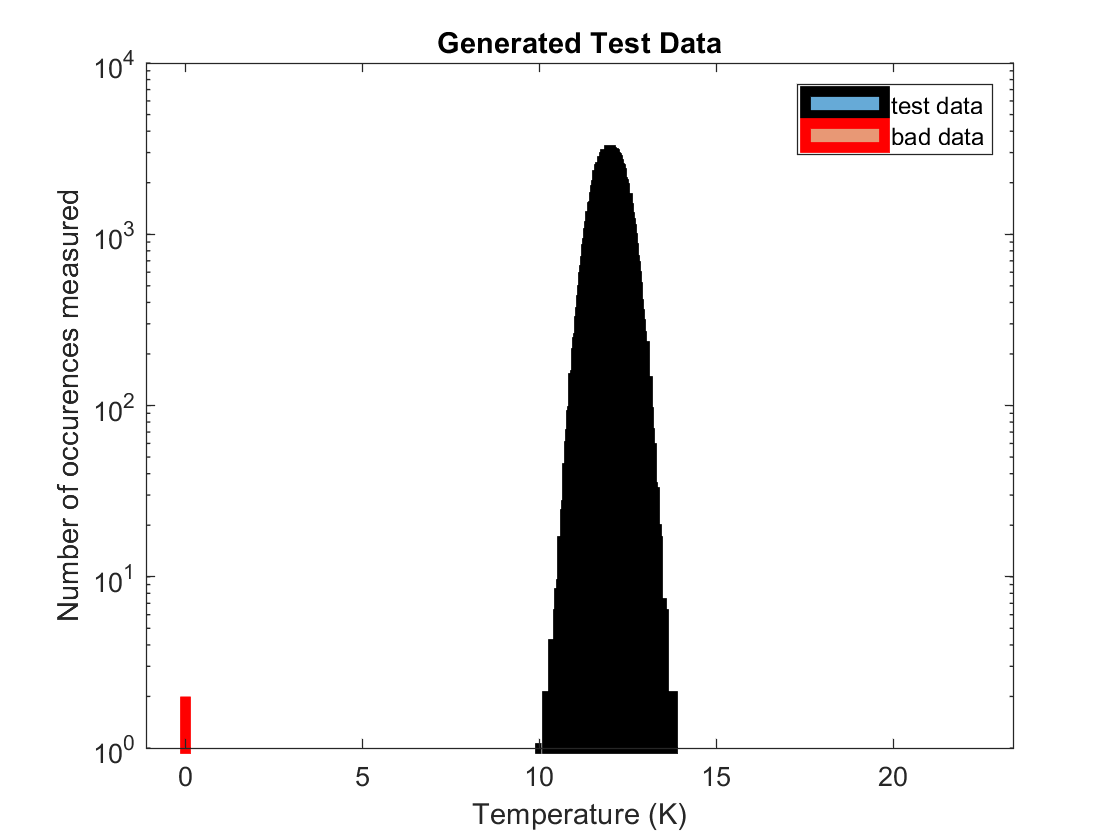

clear, close all ,clc

x = linspace(0,40,100008);
sig = 0.4;
mu = 12;
test_dat = normrnd(mu,sig,[1,100000]);
histogram(test_dat,"LineWidth",4);
hold on

bad_dat = [10 10.3 2.1 0 0 15.6 22.3 12.7];
histogram(bad_dat,100000, 'Linewidth', 4,'EdgeColor','r')
set(gca,'YScale','log')

title('Generated Test Data')
xlabel('Temperature (K)')
ylabel('Number of occurences measured')
legend('test data', 'bad data')

We are going to find the test_data points that are beyond 4*sigma from the mean on both sides. This questions allows us to throw out potentially anomalous readings that would skew our data while not throwing out large parts of potentially fine data. There would only be a chance of 6.33 in 100000 that the temperature reall was beyond that 4*sigma boundary.

gaus = makedist('Normal', mu,sig);
figure
histogram(test_dat,"LineWidth",4);
hold on
set(gca,'YScale','log')
histogram(bad_dat,100000, 'Linewidth', 4,'EdgeColor','r')
ylim([1 10^4])
fitted_dist = 3500*pdf(gaus,x);
semilogy(x,fitted_dist,'LineWidth',4)
legend('Test Data', 'Bad Data','Background Distribution')
title('Generated Test Data with Fitted Distribution')
xlabel('Temperature (K)')
ylabel('Number of occurences')


full_dat = test_dat;
full_dat(100001:100008) = bad_dat;

i = 1;

for k = 1:length(full_dat)
    if full_dat(k) < mu-4*sig || full_dat(k) > mu+4*sig
        bad(i) = full_dat(k);
        i = i + 1;
    end
end


Truth Table

Your Test Good      10         99990

Your Test Bad         7              1         

B: We ommited 10 of the true data out of 100000 true data measurements. We ommited 7 out of the 8 erroneous data measurements. This is a predictable quantity since we based our filter off a sigma value. In this case we threw out values above a sigma of 4 and below a sigma of 4. Statistically we should expect to see 6.3 of the true data be thrown out using this sigma value.

C: There was one remaining erroneous data point but it is only 1 point out of 99991 data points so it will be lost in the noise. They aren't easily avoidable using the same filter I was and adjusting the sigma value to throw it out as you would need to throw out roughly 8135 points of good data.

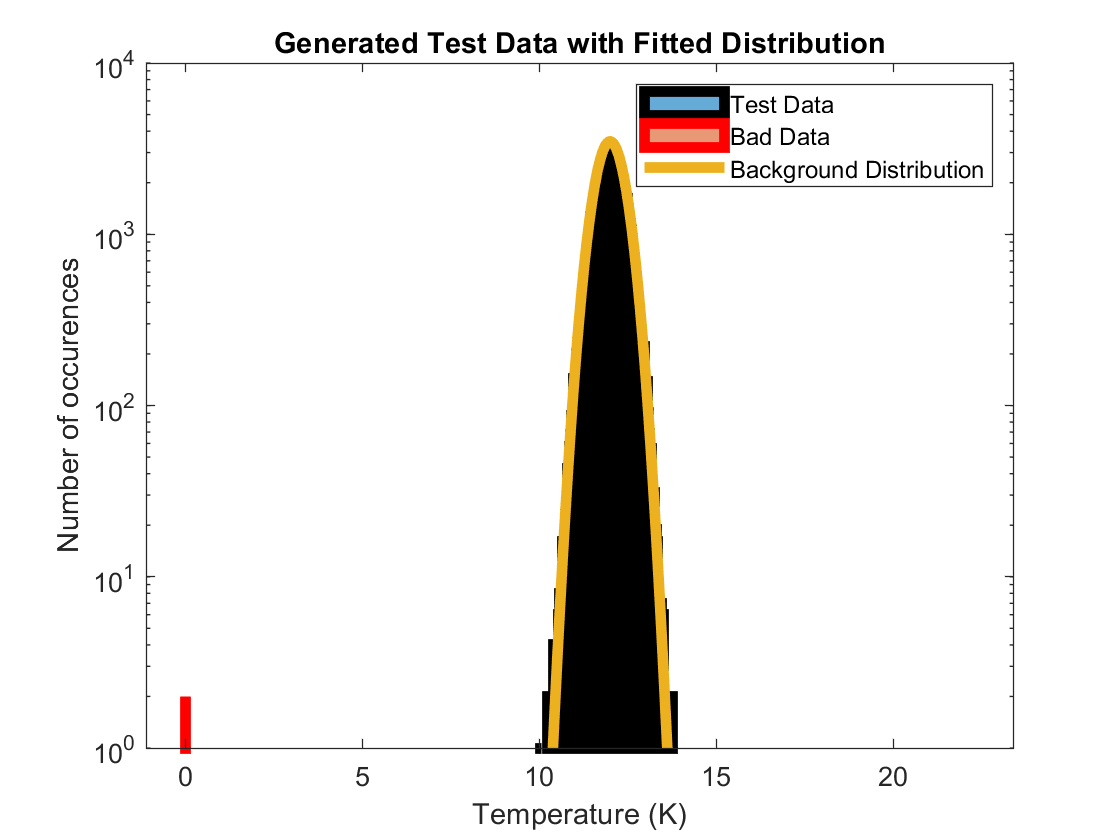

hold off

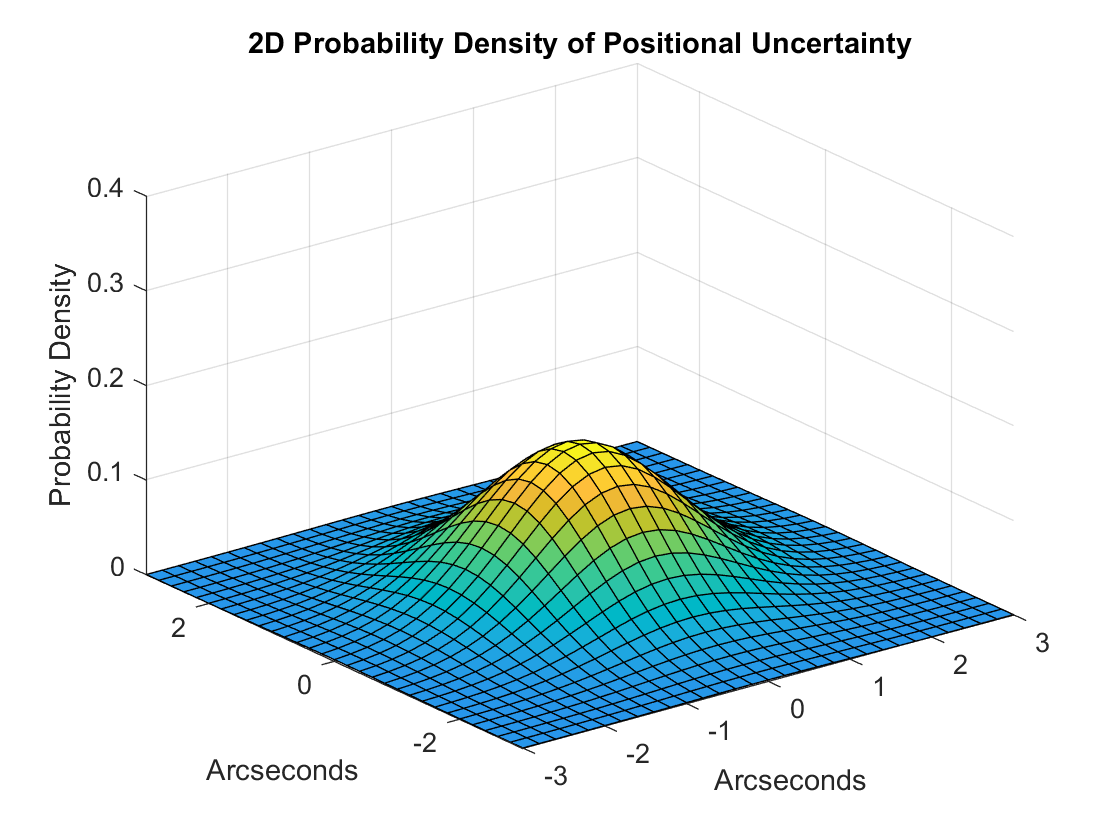

mu = [0 0];
Sigma = [1 0; 0 1];
x1 = -3:0.2:3;
x2 = -3:0.2:3;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)];
y = mvnpdf(X,mu,Sigma);
y = reshape(y,length(x2),length(x1));
surf(x1,x2,y)
caxis([min(y(:))-0.5*range(y(:)),max(y(:))])
axis([-3 3 -3 3 0 0.4])
xlabel('Arcseconds')
ylabel('Arcseconds')
zlabel('Probability Density')
title('2D Probability Density of Positional Uncertainty')

Starting at the peak, what radius would give a sigma value of 5 using a rayleigh distribution. This is because to standard normal distributions multiplied together is chi-squared, then if there is 2 degrees of freedom it would be an exponential and finally if you take the square root it would be a rayleigh.

Mathematically we want to take the probability of a sigma value of 5 on a  normal distribution and input that into the icdf of a rayleigh distribution.

x = linspace(0,10,100000);
sig =1;
rayl = makedist("Rayleigh",sig);
Rayl = pdf(rayl,x);
prob_5sig = 1-cdf("Normal",5,0, sig)

prob_5sig =      2.866515719235352e-07


x = raylinv(prob_5sig,sig)

x =      7.571678981680416e-04


The distance in arch seconds is 7.5717E-4 for a 5 sigma detection of movment.

Problem 3

We want to find the probability that the moon exists purely based on the number of cosmic ray returns in an open "moon patch" size of sky versus looking directly at the moon. 

Mathematically we want to  first find the probability of oberserving 6800 cosmic rays so we will use a Poisson distribtution with a mean of 7200 (based on the 1 ray per minute*60minutes*8hours*15days) to model the background as since it would be impossible to get a negative number of occurences. To find the probability we will take 1-cdf(poisson,6800,7200) since we want the probability of the background distribution causing there to only be 6800 occurences. Once we have that we want the sigma value so we will take the icdf of a standard normal distribution using that probability which will result in our sigma value. Our calculated sigma value is 4.75, not quite the 5 sigma value needed for a discovery. Although if we observed for more then 15 days we would get a larger value of sigma and therefore a discovery, the moon exists.

X = 7200;
x = 5400:9600;
poisson = makedist("Poisson", 'lambda',X);
stairs(x,pdf(poisson,x),"LineWidth",4);
set(gca,'YScale','log')
prob_moon = 1-cdf("Poisson", 6800,X)

prob_moon =    0.999998986671982


sig_val = icdf("Normal",prob_moon,0,1)

sig_val =    4.750747965778663


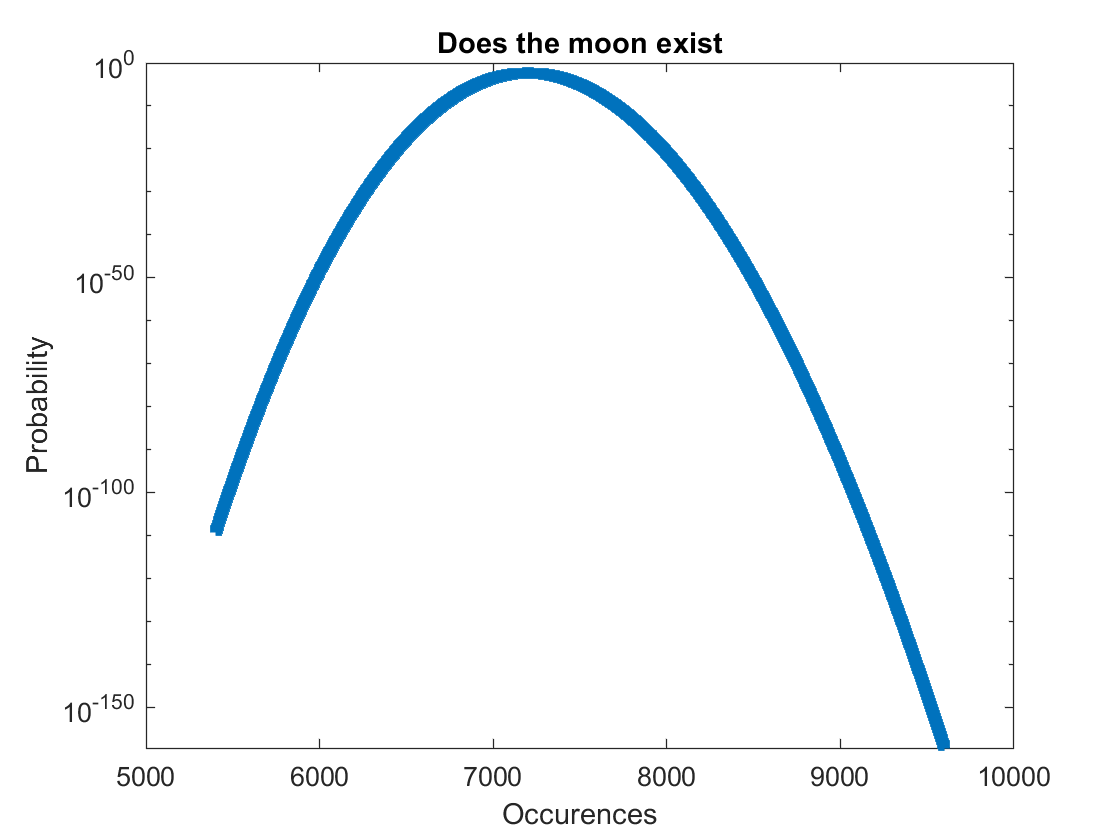

title('Does the moon exist')
ylabel('Probability')
xlabel('Occurences')